# Sistemas de 2do orden

Función de transferecnia general:

#### 
$$G(s) = \frac{\omega_n^2}{s^2 + 2\xi\omega_n s +\omega_n^2}}$$


s = tf('s');

No amortiguada: $\xi = 0
$

wn = 1;
cita = 0;

G = wn^2/(s^2 + 2*cita*wn*s + wn^2);
pole(G)

ans =    0.0000 + 1.0000i
   0.0000 - 1.0000i


disp('No amortiguada')

No amortiguada


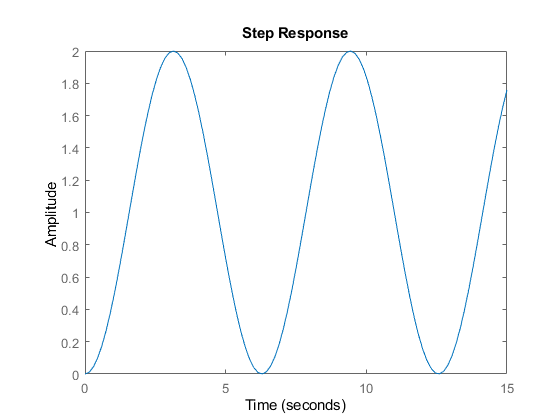

step(G,15)

Sub amortigada: $0 < \xi < 1 $

wn = 1;
cita = 0.8;

G = wn^2/(s^2 + 2*cita*wn*s + wn^2);
pole(G)

ans =   -0.8000 + 0.6000i
  -0.8000 - 0.6000i


disp('Sub amortiguada')

Sub amortiguada


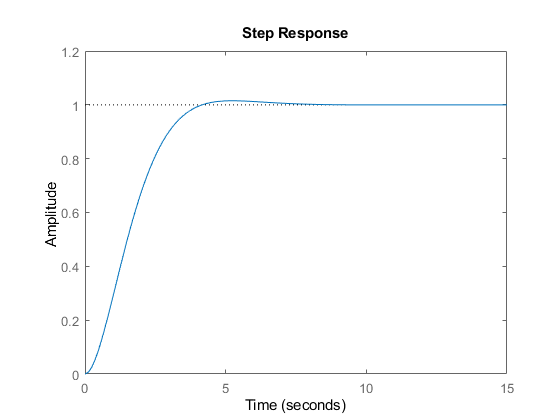

step(G,15)

Criticamente amortiguada: $\xi = 1$

wn = 1;
cita = 1;

G = wn^2/(s^2 + 2*cita*wn*s + wn^2);
pole(G)

ans =     -1
    -1


disp('Criticamente amortiguada')

Criticamente amortiguada


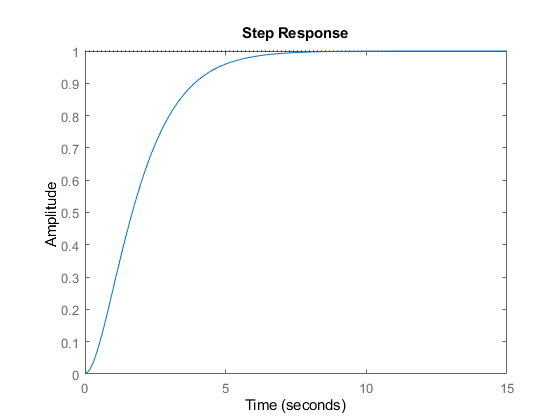

step(G,15)

Sobre amortiguada: $\xi > 1$

wn = 1;
cita = 1.5;

G = wn^2/(s^2 + 2*cita*wn*s + wn^2);
pole(G)

ans =    -1.5583
   -0.6417


disp('Sobre amortiguada')

Sobre amortiguada


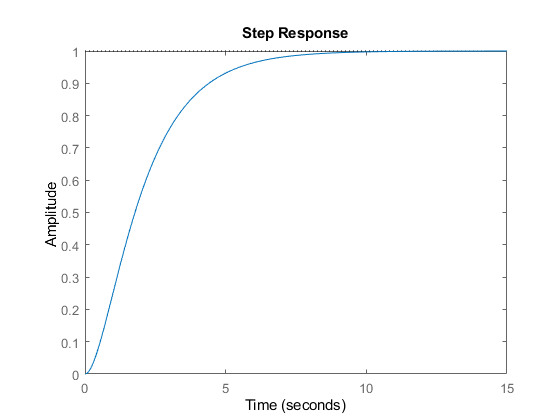

step(G,15)